Rg_T = zeros (31,1);
Std_Rg_T = zeros (31,1);
Swip = 100

Swip = 100

parfor j = 1:31
walk_start = 20;
walk_lenght = 50;
walk_number = 1000;
Rg_T_down  = zeros(Swip,1);

for i  = 1:Swip

 %[walk_lenght,~,~,Rg,~] = Many_GSAW2d_statistics(walk_lenght,walk_number,j/10);
 [walk_lenght,Rg,~] = Many_GSAW2d_statistics_notw(walk_lenght,walk_number,j/10);

% passiamo ai logaritmi scartando l'ultimo step e i primi fino a walk start
    N= 1:walk_lenght;
    N_log = log ( N(walk_start : (walk_lenght-1))' );
    R_log = log ( Rg(walk_start : (walk_lenght-1)) );


f = fit(N_log,R_log,'poly1',"Weights",ones(walk_lenght-walk_start,1));
Rg_T_down(i) = f.p1;
end
Rg_T(j) = mean(Rg_T_down);
Std_Rg_T(j) = std(Rg_T_down)/sqrt(Swip);
fprintf("swip N. %g \n", j)
end

swip N. 4 
swip N. 3 
swip N. 2 
swip N. 1 
swip N. 7 
swip N. 10 
swip N. 13 
swip N. 16 
swip N. 6 
swip N. 5 
swip N. 9 
swip N. 8 
swip N. 12 
swip N. 15 
swip N. 11 
swip N. 14 
swip N. 22 
swip N. 21 
swip N. 24 
swip N. 23 
swip N. 20 
swip N. 18 
swip N. 19 
swip N. 17 
swip N. 25 
swip N. 26 
swip N. 27 
swip N. 28 
swip N. 29 
swip N. 30 
swip N. 31 


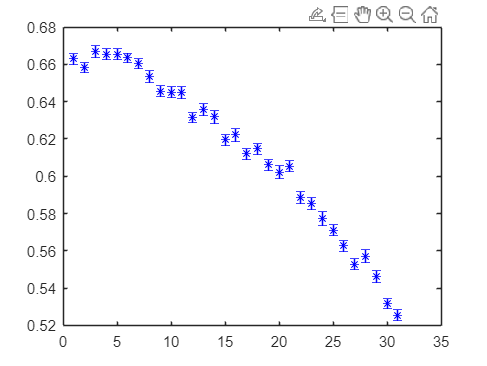

errorbar (1:31,Rg_T,Std_Rg_T,"b*")